## Trapezoidal vs. Simpson - ex. 9.2

clear all;
close all;
clc;

Consider the following integral:


$$I = \int_{-1}^1 \sqrt{1 - x^2} dx = \frac{\pi}{2}$$


int = pi / 2;
f = @(x) sqrt(1 - x.^2);
a = -1;
b = 1;

### a. Compute $I$ using the composite trapezoidal and Simpson rules with a number of nodes $n=3^k$, with $k = 1,...,9$

int_t = zeros(9, 1);
int_s = zeros(9, 1);
n = zeros(9, 1);
m_t = zeros(9, 1);
m_s = zeros(9, 1);

for k = 1:9
    n(k) = 3^k;
    m_t(k) = n(k) - 1;
    m_s(k) = (n(k) - 1) / 2;
    
    int_t(k) = ctrapezoidal(a, b, m_t(k), f);
    int_s(k) = csimpson(a, b, m_s(k), f);
end

int_t

int_t =     1.0000
    1.4979
    1.5583
    1.5685
    1.5704
    1.5707
    1.5708
    1.5708
    1.5708


int_s

int_s =     1.3333
    1.5418
    1.5659
    1.5699
    1.5706
    1.5708
    1.5708
    1.5708
    1.5708


### b. Estimate the order of accuracy of the two methods

err_t = abs(int - int_t);
err_s = abs(int - int_s);

p_t = -diff(log(err_t)) / log(3)

p_t =     1.8727
    1.6045
    1.5331
    1.5109
    1.5036
    1.5012
    1.5004
    1.5001


p_s = -diff(log(err_s)) / log(3)

p_s =     1.9140
    1.6156
    1.5366
    1.5120
    1.5040
    1.5013
    1.5004
    1.5001


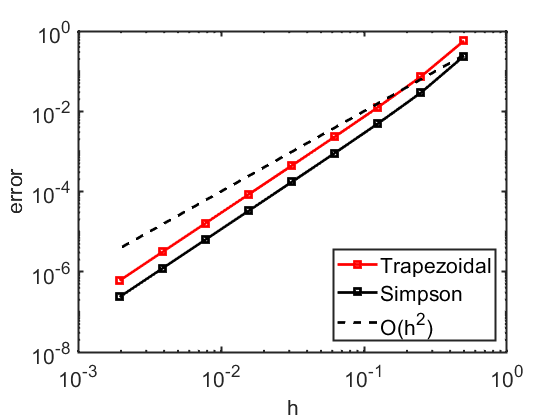


h = 1./2.^[1:9]; % [1/1; 1/2; 1/4; ...; 1/2^9]
figure
loglog(h, err_t, 'rs-', 'LineWidth', 2)
hold on, box on
loglog(h, err_s, 'ks-', 'LineWidth', 2)
loglog(h, h.^2, 'k--', 'LineWidth', 2)
set(gca,'FontSize',16)
set(gca,'LineWidth',1.5)
xlabel('h','FontSize',16)
ylabel('error','FontSize',16)
leg = legend('Trapezoidal', 'Simpson', 'O(h^2)', 'Location', 'SouthEast');
set(leg,'FontSize',16)
set(leg,'LineWidth',1.5)

The rate of convergence of the two methods is 1.5: the reduction of the order of accuracy is due to the fact that the integrand function is not sufficiently smooth to apply the previous convergence results ($C^2$ regularity for the trapezoidal rule, $C^4$ regularity for the Simpson rule, but the function is only $C^0$).

function res = trapezoidal(a, b, f)
    res = ((b-a)/2)*(f(a) + f(b));
end

function res = simpson(a, b, f)
    res = ((b-a)/6)*(f(a) + f(b) + 4*f((a+b)/2));
end

function int = ctrapezoidal(a, b, m, f)
    x = linspace(a, b, m+1);
	int = 0;

	for i = 1:m
		int = int + trapezoidal(x(i), x(i+1), f);
    end
end

function int = csimpson(a, b, m, f)
    x = linspace(a, b, m+1);
	int = 0;

	for i = 1:m
		int = int + simpson(x(i), x(i+1), f);
    end
end
